clear all
clc
close all

Read Audio

% Reading the audioo file, finding sampling frequency, and the type of channel
filename= "test.wav";
[Audio, fs]= audioread(filename);  %Read the audio file
info=audioinfo(filename);
NumChannels = info.NumChannels;

%Check if the audio file is mono or stereo
if(NumChannels == 1)
    Audio_Signal = Audio(:,1);
else
    Audio_Signal = [Audio(:,1)', Audio(:,2)']';
end

Quantization and Encoding

% define number of bits for quantization, quantize the signal and encode it
n_bits = 8;
n_levels = 2^n_bits;

[Quantized_Samples, Levels] = Quantizer(Audio_Signal, n_bits);
Bit_Stream = Encoder(Quantized_Samples, n_levels);

Modulator

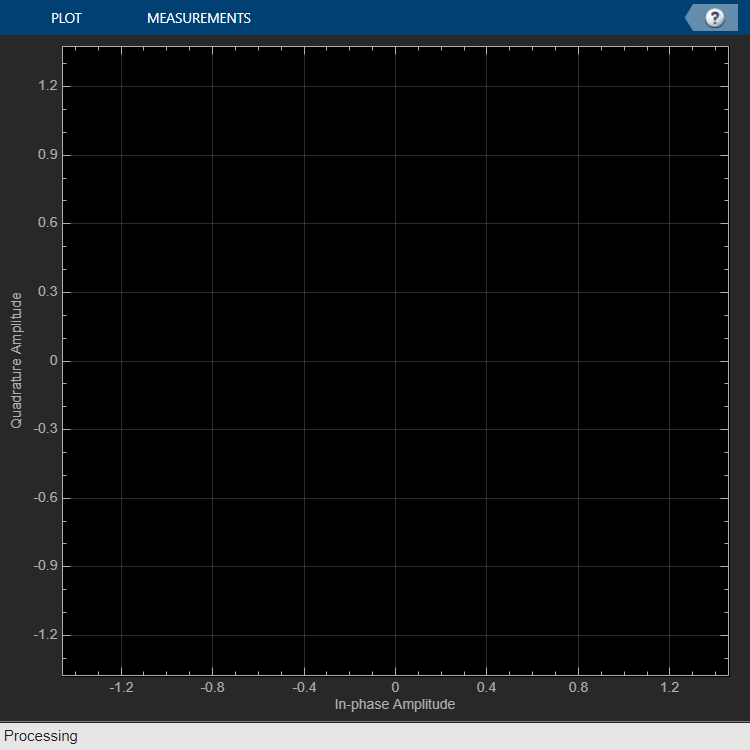

modulator = comm.PSKModulator(8,pi/8,"BitInput",true);
mod_bits = modulator(Bit_Stream');

%Constellation Diagram
constDiagram1 = comm.ConstellationDiagram('ShowTrajectory',true,'ShowReferenceConstellation',false); 
constDiagram1(mod_bits);

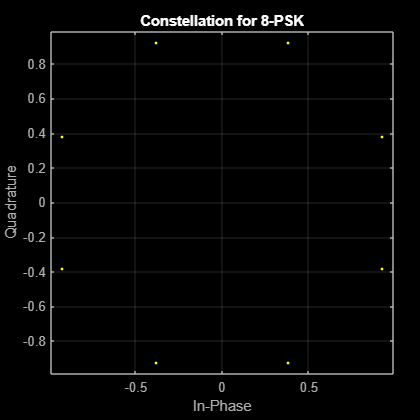

scatterplot(mod_bits);
title('Constellation for 8-PSK'); grid on;

Channel

rayleighchan = comm.RayleighChannel('SampleRate', fs,...
    'MaximumDopplerShift',30, ...
    'PathDelays',[550 700 600]*1e-9, ...
    'AveragePathGains',[1.5 0.8 0.5], ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',                 22, ...
    'FadingTechnique','Filtered Gaussian noise');

ricianchan = comm.RicianChannel('SampleRate', fs,...
    'MaximumDopplerShift',30, ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',                22,...
    'PathDelays',[0.0 600 500]*1e-9, ...
    'AveragePathGains',[1 1.5 0.8], ...
    'KFactor',5, ...
    'FadingTechnique','Filtered Gaussian noise');

%The AWGN channel simulates the interfrence between more than 2 bluetooth
%devices or with IEEE 802.11 WLAN.
AWGchan = comm.AWGNChannel('EbNo',9,'BitsPerSymbol',2);

AWGchan = comm.AWGNChannel('EbNo',15,'BitsPerSymbol',2);

Adding Noise to bits

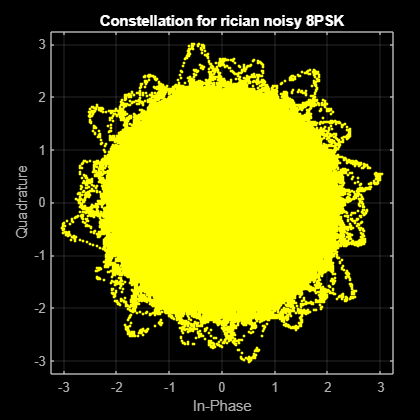

mod_bits_RG = rayleighchan(mod_bits);
mod_bits_rician = ricianchan(mod_bits);
mod_bits_AWGN = AWGchan(mod_bits);
scatterplot(mod_bits_rician);
title('Constellation for rician noisy 8PSK'); grid on;

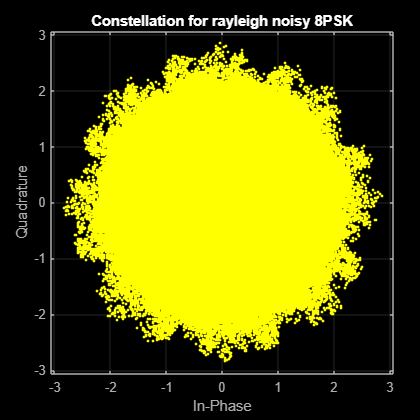

scatterplot(mod_bits_RG);
title('Constellation for rayleigh noisy 8PSK'); grid on;

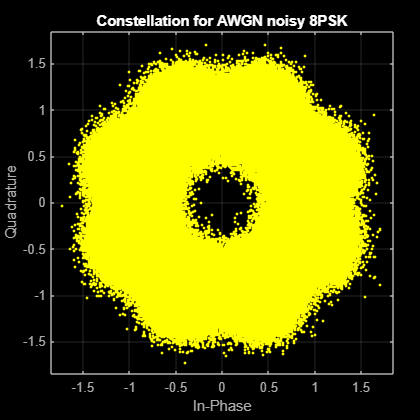

scatterplot(mod_bits_AWGN);
title('Constellation for AWGN noisy 8PSK'); grid on;

Demodulator

demodulator = comm.PSKDemodulator('BitOutput',true);
demod_RG = demodulator(mod_bits_RG);
demod_rician = demodulator(mod_bits_rician);
demod_AWGN = demodulator(mod_bits_AWGN);

Decoder

Decoded_Signal_RG = Decoder(demod_RG', Levels);
if(NumChannels == 1)
    Output_AudioSignal_RG = Decoded_Signal_RG;
else
    Output_AudioSignal_RG = [Decoded_Signal_RG(1:length(Decoded_Signal_RG)/2)', Decoded_Signal_RG(length(Decoded_Signal_RG)/2 +1:end)'];
end
Decoded_Signal_Ri = Decoder(demod_rician', Levels);
if(NumChannels == 1)
    Output_AudioSignal_Ri = Decoded_Signal_Ri;
else
    Output_AudioSignal_Ri = [Decoded_Signal_Ri(1:length(Decoded_Signal_Ri)/2)', Decoded_Signal_Ri(length(Decoded_Signal_Ri)/2 +1:end)'];
end
Decoded_Signal_AW = Decoder(demod_AWGN', Levels);
if(NumChannels == 1)
    Output_AudioSignal_AW = Decoded_Signal_AW;
else
    Output_AudioSignal_AW = [Decoded_Signal_AW(1:length(Decoded_Signal_AW)/2)', Decoded_Signal_AW(length(Decoded_Signal_AW)/2 +1:end)'];
end

Saving Output

audiowrite('RG_QPSK.wav',Output_AudioSignal_RG, fs);
audiowrite('Ri_QPSK.wav',Output_AudioSignal_Ri, fs);
audiowrite('AWGN_8PSK_2.wav',Output_AudioSignal_AW, fs);

BER Comparission

BER_RG_8PSK = biterr(Bit_Stream, demod_RG')/ length(Bit_Stream)

BER_RG_8PSK = 0.5000

BER_Rician_8PSK = biterr(Bit_Stream, demod_rician')/ length(Bit_Stream)

BER_Rician_8PSK = 0.5044

BER_AWGN_8PSK = biterr(Bit_Stream, demod_AWGN')/ length(Bit_Stream)

BER_AWGN_8PSK = 0.0104

BER Plots

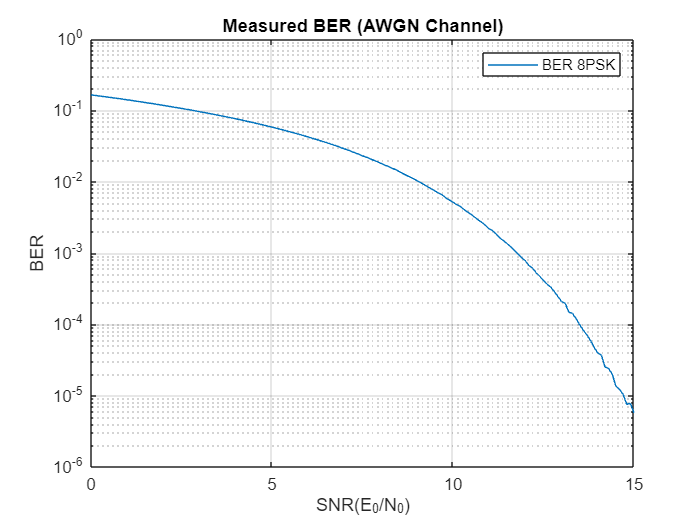

%AWGN
BER =[];
SNR = 0:0.1:15;
for i =1: length(SNR)
    awgnchannel = comm.AWGNChannel('EbNo',SNR(i),'BitsPerSymbol',2);
    audio_mod_awgn= awgnchannel(mod_bits);
    out_bits=(demodulator(audio_mod_awgn)');
    [nu,ratio]=biterr(out_bits,Bit_Stream);
    BER=[BER,ratio];
end
figure();
semilogy(SNR, BER); title("Measured BER (AWGN Channel)"); xlabel("SNR(E_0/N_0)"); ylabel("BER"); grid on; hold on;
legend('BER 8PSK')

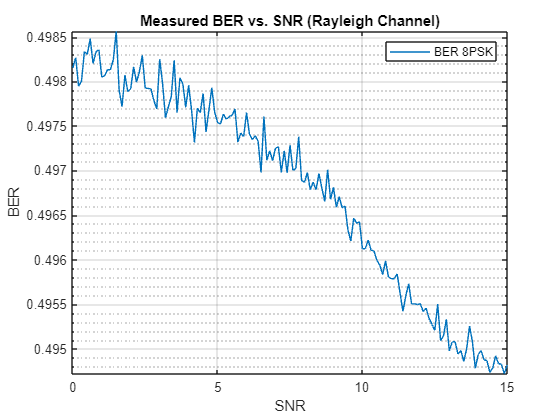

BER =[];
PathGains = 0:0.1:15;
for i =1: length(PathGains)
    rayleighchan = comm.RayleighChannel('SampleRate', fs,...
    'MaximumDopplerShift',30, ...
    'PathDelays',[0.0 200]*1e-9, ...
    'AveragePathGains',[1 PathGains(i)], ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',                 22, ...
    'FadingTechnique','Filtered Gaussian noise');
    
    
    audio_mod_re= rayleighchan(mod_bits);
    awgnchannel = comm.AWGNChannel('EbNo',PathGains(i),'BitsPerSymbol',2);
    audio_mod_awgn= awgnchannel(audio_mod_re);
    out_bits=(demodulator(audio_mod_awgn)');
    [nu,ratio]=biterr(out_bits,Bit_Stream);
    BER=[BER,ratio];
end
figure();
semilogy(PathGains, BER); title("Measured BER vs. SNR (Rayleigh Channel)"); xlabel("SNR"); ylabel("BER"); grid on; hold on;
legend('BER 8PSK')

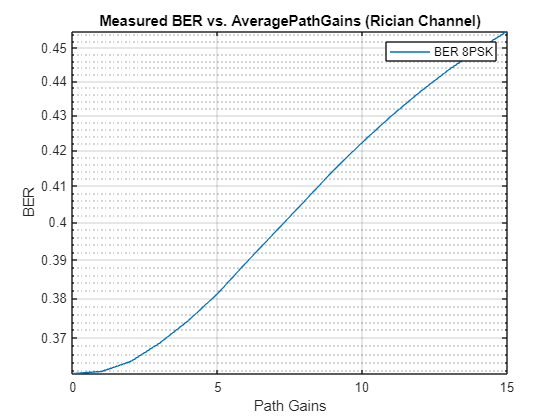

BER =[];
PathGains = 0:1:15;
for i =1: length(PathGains)
    rayleighchan = comm.RicianChannel('SampleRate', fs,...
    'MaximumDopplerShift',30, ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',                22,...
    'PathDelays',[0.0 100 200]*1e-9, ...
    'AveragePathGains',[1 0.5 PathGains(i)], ...
    'KFactor',5, ...
    'FadingTechnique','Filtered Gaussian noise');
    
    audio_mod_re= rayleighchan(mod_bits);
    awgnchannel = comm.AWGNChannel('EbNo',PathGains(i),'BitsPerSymbol',2);
    audio_mod_awgn= awgnchannel(audio_mod_re);
    out_bits=(demodulator(audio_mod_awgn)');
    [nu,ratio]=biterr(out_bits,Bit_Stream);
    BER=[BER,ratio];
end
figure();
semilogy(PathGains, BER); title("Measured BER vs. AveragePathGains (Rician Channel)"); xlabel("Path Gains"); ylabel("BER"); grid on; hold on;
legend('BER 8PSK')